# Load data


dataPath = fullfile("Data/location_data (1)");
dataDirectory = dir(dataPath);
bikeData = [];

% for i = 3:length(dataDirectory)

for i = 3:4 % The first to paths point to the directory itself and the top directory
    baseFileName = dataDirectory(i).name;
    fullFileName = fullfile(dataPath, baseFileName);
    table = readtable(fullFileName);
    bikeData{end+1} = table(:, [2, 5:15, 17]);
end


for i = 1:length(bikeData)
    bikeData{i}.("toSend") = true(height(bikeData{i}), 1);

    currentData = bikeData{i};

    beginx = currentData.longitude(1);
    beginy = currentData.latitude(1);
end

Now, the GPS coordinates are converted to (x, y) coordinates.

## Setting parameters for the simulation

global beginIteration
global endIteration
global newSimulation
eventBased = true;
newSimulation = false;

% beginIteration = 2150;
% endIteration = 2350;
% beginIteration = 600;
% endIteration = 700;
beginIteration = 1;
endIteration = height(bikeData{1});

## Calculating xy coordinates from GPS data and rotating bike paths

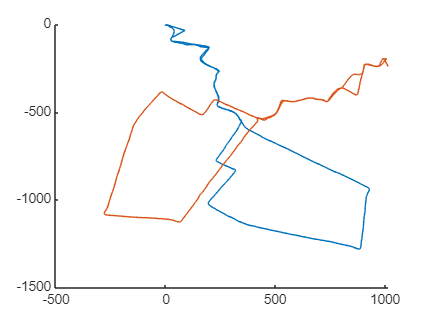

alt = 30;  % 30 meters is an approximate altitude in Enschede
origin = [bikeData{1}.latitude(1), bikeData{1}.longitude(1), alt];

for i = 1:length(bikeData)
    currentData = bikeData{i};
    hold on
    [x,y] = latlon2local(currentData.latitude, currentData.longitude, alt, origin);
    hold off
    bikeData{i}.("x") = x;
    bikeData{i}.("y") = y;
end
% hold off

newCoordinates = line(bikeData{2}.x, bikeData{2}.y);
rotate(newCoordinates, [0 0 1], -90);

bikeData{2}.x = transpose(newCoordinates.XData);
bikeData{2}.y = transpose(newCoordinates.YData);

figure

hold on
for i = 1:length(bikeData)
    % plot(bikeData{i}.x, bikeData{i}.y)
    scatter(bikeData{i}.x, bikeData{i}.y, 10, "filled", MarkerFaceColor="blue");
end
hold off




for i = 1:length(bikeData)
    bikeData{i}.("heading") = zeros(height(bikeData{i}), 1);
    for j = 2:height(bikeData{i})
        currentPos = table2array(bikeData{i}(j, ["x", "y"]));
        previousPos = table2array(bikeData{i}(j-1, ["x", "y"]));
        if currentPos ~= previousPos
            heading = [currentPos(1) - previousPos(1), ...
                currentPos(2) - previousPos(2)];

            angle = rad2deg(atan2(heading(2), heading(1)));
            bikeData{i}.heading(j) = angle;
        else
            bikeData{i}.heading(j) = bikeData{i}.heading(j-1);
        end
    end
end

Determine which messages the nodes should receive

## Creating grid of listener nodes

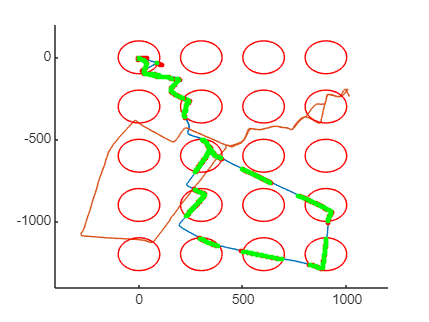

networkSimulator = wirelessNetworkSimulator.init;

amountX = 3;
amountY = 4;

function [nodes, receivedData] = createGrid(amountX, amountY)
    distance = 300;
    nodes = [];
    storageArray = [];
    nodeNames = string;
    nodeID = 1;

    for y = 0:distance:amountY*distance
        for x = 0:distance:amountX*distance
            config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(nodeID,4),...
                NetworkTransmissions=1);
            node = bluetoothLENode("broadcaster-observer", Name="Grid" + nodeID);
            node.Position = [x -y 0];
            nodes{end+1} = node;
            storageArray{nodeID} = uint32.empty(2, 0);
            nodeNames(nodeID) = node.Name;
            nodeID = nodeID + 1;
        end
    end

   receivedData = dictionary(nodeNames, storageArray);
end

global receivedData;
[grid, receivedData] = createGrid(amountX, amountY);

function h = circle(x,y,r)
    hold on
    th = 0:pi/50:2*pi;
    xunit = r * cos(th) + x;
    yunit = r * sin(th) + y;
    h = plot(xunit, yunit, Color="red", MarkerSize=0.1);
    hold off
end

hold on
for i=1:length(grid)
    circle(grid{i}.Position(1), grid{i}.Position(2), 100);
end
hold off

## Determine which messages each listener node should receive

function x = inRange(position1, position2)
    distance = pdist2(position1, position2);
    x = distance < 100;
end

function toReceive = determineToReceive(grid, bikeData)
    global beginIteration
    global endIteration
        
    for k = 1:length(grid)
        toReceive{k} = uint32.empty(2, 0);
        for i = 1:length(bikeData)
            for j = beginIteration:endIteration
                messagePosition = [bikeData{i}.x(j) bikeData{i}.y(j)];
                if (inRange(grid{k}.Position([1 2]), messagePosition)) && (bikeData{i}.toSend(j))
                    toReceive{k}(:, end + 1) = [uint32(length(grid) + i) uint32(j)];
                end
            end
        end
    end
end

function toReceive = determineToReceiveBikes(bikes, bikeData, gridLength)
    global beginIteration
    global endIteration

    for k = 1:length(bikes)
        toReceive{k} = uint32.empty(2, 0);
        for i = 1:length(bikeData)
            if i ~= k
                for j = beginIteration:endIteration
                    position1 = [bikeData{k}.x(j) bikeData{k}.y(j)];
                    position2 = [bikeData{i}.x(j) bikeData{i}.y(j)];
                    if inRange(position1, position2) && bikeData{i}.toSend(j)
                        toReceive{k}(:, end + 1) = [uint32(gridLength + i) uint32(j)];
                    end
                end
            end
        end
    end
end

toReceive = determineToReceive(grid, bikeData);


Setup simulation

## Setup simulation

numNodes = 3;

config = bluetoothMeshProfileConfig(ElementAddress=dec2hex(length(grid)+1, 4),...
        NetworkTransmissions=1);

config.Relay = false;


bike1 = bluetoothLENode("broadcaster-observer", Name="Bike1", MeshConfig=config);
bike2 = bluetoothLENode("broadcaster-observer", Name="Bike2", MeshConfig=config);

receivedData(bike1.Name) = {uint32.empty(2, 0)};
receivedData(bike2.Name) = {uint32.empty(2, 0)};


bikes = {bike1 bike2};

toReceive = [toReceive determineToReceiveBikes(bikes, bikeData, length(grid))];

global traffic
traffic = dictionary;

for i = 1:length(bikes)
    traffic{bikes{i}.Name} = networkTrafficOnOff(OnTime=0.02, OffTime=0.08, PacketSize=8, GeneratePacket=true, DataRate=10);
    addTrafficSource(bikes{i}, traffic{bikes{i}.Name}, ...
        SourceAddress=bikes{i}.MeshConfig.ElementAddress, ...
        DestinationAddress=grid{5}.MeshConfig.ElementAddress);
end

global iteration
iteration = uint32(beginIteration);

Create listener to process received data

function processData(Node, EventData)
    global receivedData;
    message = EventData.Data.Message;

    received_id = typecast(uint8(transpose(message)), 'uint32');
    receivedData{Node.Name}(:, end+1) = received_id;
end

for i = 1:length(grid)
    addlistener(grid{i}, "MeshAppDataReceived", @processData);
end

for i = 1:length(bikes)
    addlistener(bikes{i}, "MeshAppDataReceived", @processData);
end

Create listener for sending data

function transmitData(node, EventData)
    global traffic
    traffic{node.Name}.OffTime = 1;
end

% addlistener(bike1, "PacketTransmissionStarted", @transmitData);
% addlistener(bike2, "PacketTransmissionStarted", @transmitData);


Create function which sets position of the bike 

function sendData(~, userData)
    global iteration;

    for i = 1:(length(userData.bikes))
        if userData.bikeData{i}.toSend(iteration)
            userData.bikes{i}.Position = [userData.bikeData{i}.x(iteration) ...
                userData.bikeData{i}.y(iteration) 0];
            
            bytes = typecast([userData.bikes{i}.ID iteration], "uint8");
            userData.traffic{userData.bikes{i}.Name}.ApplicationData = bytes;
            userData.traffic{userData.bikes{i}.Name}.OffTime = 0;
        else
            userData.traffic{userData.bikes{i}.Name}.OffTime = ...
                userData.traffic{userData.bikes{i}.Name}.OffTime + 0.1;
        end
    end
    
    iteration = iteration + 1;
end

% simulationData = struct;
% simulationData.bikeData = bikeData;
% simulationData.simulator = networkSimulator;
% simulationData.bikes = bikes;
% simulationData.traffic = traffic;

addNodes(networkSimulator, grid);
addNodes(networkSimulator, bikes);
% scheduleAction(networkSimulator, @sendData, simulationData, 0, 0.1);

Bluetooth messages will now be simulated

## Run simulation

function stats = runSimulation(networkSimulator, toReceive, simulationData)
    global beginIteration
    global endIteration
    global iteration
    global receivedData
    global newSimulation


    
    % addNodes(networkSimulator, grid);
    % addNodes(networkSimulator, bikes);
    scheduleAction(networkSimulator, @sendData, simulationData, 0, 0.1);


    
    if newSimulation
        simulationTime = (endIteration - beginIteration) / 10
        startTime = datetime;
        fprintf("%s: Starting simulation\n", startTime)
        % run(networkSimulator,simulationTime);
        endTime = datetime;
        fprintf("%s: Simulation ended", endTime)
        iteration
    else
        load("Output\results\event_based_simulation_15-1-2025_12.11.mat");
    end

    totalReceived = 0;
    totalExpected = 0;

    for i = 1:length(toReceive)
        if length(toReceive{i}) >= 1
            fprintf("%i: Data of %s:", i, networkSimulator.Nodes{i}.Name)
            received = unique(receivedData{networkSimulator.Nodes{i}.Name}.', "rows").'
            expected = toReceive{i}
            correctlyReceived = 0;
        
            for j=1:length(toReceive{i})
                % toReceive{i}(:, j)
                if ismember(toReceive{i}(:, j), receivedData{networkSimulator.Nodes{i}.Name})
                    correctlyReceived = correctlyReceived + 1;
                end
            end
            
            correctlyReceived
            fractionCorrect = correctlyReceived/length(toReceive{i})

            totalReceived = totalReceived + correctlyReceived;
            totalExpected = totalExpected + length(toReceive{i});
        end


    end
    
    totalExpected
    totalReceived
    totalFractionCorrect = totalReceived/totalExpected
    
    stats = [];
    for i=1:length(networkSimulator.Nodes)
        stats{i} = statistics(networkSimulator.Nodes{i});
    end
end


% runSimulation(networkSimulator, toReceive)
% bike1Stats = statistics(bike1)
% gridStats = statistics(grid{1})
% grid2Stats = statistics(grid{2})


## Determining which messages to send

maxGenerateTime = 5000; % the maximum time between two transmitted messages, which is 5000 ms
minDistance = 4; % minimum change in distance after last transmitted message, which is 4 meters
minSpeedChange = 5; % minimum speed change between after last transmitted message, which is 5 m/s
minheadingChange = 4; % minimum change in heading after last transmitted message, which is 4 degrees

indicesInRange = toReceive;

if eventBased
    for k=1:length(bikeData)
        lastMessage = beginIteration;
    
        for i = beginIteration:endIteration
            if bikeData{k}.timestamp_ms(i) >= bikeData{k}.timestamp_ms(lastMessage) + maxGenerateTime
                lastMessage = i;
                bikeData{k}.toSend(i) = true;
            elseif pdist2(bikeData{k}{i, ["x" "y"]}, bikeData{k}{lastMessage, ["x" "y"]}) >= minDistance
                lastMessage = i;
                bikeData{k}.toSend(i) = true;
            elseif abs(bikeData{k}.velocity(i) - bikeData{k}.velocity(lastMessage))/3.6 >= minSpeedChange
                lastMessage = i;
                bikeData{k}.toSend(i) = true;
            elseif abs(bikeData{k}.heading(i) - bikeData{k}.heading(lastMessage)) >= minheadingChange
                lastMessage = i;
                bikeData{k}.toSend(i) = true;
            else
                bikeData{k}.toSend(i) = false;
            end
        end
    end
    toReceive = determineToReceive(grid, bikeData);
    toReceive = [toReceive determineToReceiveBikes(bikes, bikeData, length(grid))];
end

## Calculate next position

function [x, y] = getNextPosition(previousPostition, speed, heading, duration)
    if nargin <= 3
        duration = 0.1;
    end
    distanceMoved = (speed/3.6)*duration;
    x = previousPostition(1) + distanceMoved * cosd(heading);
    y = previousPostition(2) + distanceMoved * sind(heading);
end

function calculatedPositions = calculatePositions(receivedMessages, expectedMessages, bikeData)
    calculatedPositions = dictionary;
    lastPosition = bikeData{expectedMessages(1), ["x" "y"]};
    speed = bikeData.velocity(expectedMessages(1));
    heading = bikeData.heading(expectedMessages(1));
    
    for i = expectedMessages
        if ismember(i, receivedMessages)
            lastPosition = bikeData{i, ["x" "y"]};
            speed = bikeData.velocity(i);
            heading = bikeData.heading(i);
        else
            [x, y] = getNextPosition(lastPosition, speed, heading);
            lastPosition = [x, y];
        end
        calculatedPositions{i} = lastPosition;
    end
end

## Running simulation

simulationData = struct;
simulationData.bikeData = bikeData;
simulationData.simulator = networkSimulator;
simulationData.bikes = bikes;
simulationData.traffic = traffic;
bikeStats = runSimulation(networkSimulator, toReceive, simulationData);

1: Data of Grid1:

received = 2×55 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
     51    101    151    201    251    301    351    424    464    514    564    624    654    664    674   7624   7634   7644   7654   7664   7674   7684   7694   7704   7714   7724   7744   7754   7774   7784   7794   7804   7814   7824   7834   7844   7854   7864   7874   7884   7894   7904   7914   7924   7964   7974   8034   8044   8094   8144


expected = 2×61 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
     51    101    151    201    251    301    351    401    424    454    464    514    564    614    624    654    664    674   7624   7634   7644   7654   7664   7674   7684   7694   7704   7714   7724   7734   7744   7754   7764   7774   7784   7794   7804   7814   7824   7834   7844   7854   7864   7874   7884   7894   7904   7914   7924   7964


correctlyReceived = 54

fractionCorrect = 0.8852

5: Data of Grid5:

received = 2×8 uint32 matrix
     22     22     22     22     22     22     22     22
   5274   5284   5294   5314   5324   5334   5344   5354


expected = 2×8 uint32 matrix
     22     22     22     22     22     22     22     22
   5274   5284   5294   5314   5324   5334   5344   5354


correctlyReceived = 8

fractionCorrect = 1

6: Data of Grid6:

received = 2×49 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   1274   1284   1294   1304   1314   1324   1354   1364   1374   1384   1394   1404   1414   1424   1434   1444   1454   1464   1474   1484   1494   1504   1514   1524   1534   1544   6794   6804   6814   6824   6834   6844   6854   6864   6874   6884   6894   6904   6914   6924   6934   6944   6954   6964   6974   6984   6994   7004   7014


expected = 2×50 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   1274   1284   1294   1304   1314   1324   1344   1354   1364   1374   1384   1394   1404   1414   1424   1434   1444   1454   1464   1474   1484   1494   1504   1514   1524   1534   1544   6794   6804   6814   6824   6834   6844   6854   6864   6874   6884   6894   6904   6914   6924   6934   6944   6954   6964   6974   6984   6994   7004   7014


correctlyReceived = 49

fractionCorrect = 0.9800

8: Data of Grid8:

received = 2×96 uint32 matrix
     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22
    734    744    754    764    774    784    794    804    814    824    834    844    854    864    874    884    894    904    914    924    934    944    954    964    984    994   1004   1014   1024   1034   1044   1054   1064   1074   1084   1114   1124   1134   1144   1154   1164   1174   1184   1194   1204   1214   1224   1234   1244   1254


expected = 2×100 uint32 matrix
     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22
    734    744    754    764    774    784    794    804    814    824    834    844    854    864    874    884    894    904    914    924    934    944    954    964    974    984    994   1004   1014   1024   1034   1044   1054   1064   1074   1084   1104   1114   1124   1134   1144   1154   1164   1174   1184   1194   1204   1214   1224   1234


correctlyReceived = 96

fractionCorrect = 0.9600

10: Data of Grid10:

received = 2×97 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   1854   1864   1874   1884   1894   1904   1914   1924   1934   1944   1954   1964   2034   2084   2114   2134   2144   2154   2164   2174   2184   2194   2204   2214   2224   2234   2244   2254   2264   2274   2284   2304   5894   5904   5914   5924   5934   5944   5954   5964   5974   5984   5994   6004   6014   6024   6034   6044   6054   6064


expected = 2×102 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   1854   1864   1874   1884   1894   1904   1914   1924   1934   1944   1954   1964   2004   2034   2084   2114   2134   2144   2154   2164   2174   2184   2194   2204   2214   2224   2234   2244   2254   2264   2274   2284   2294   2304   5894   5904   5914   5924   5934   5944   5954   5964   5974   5984   5994   6004   6014   6024   6034   6044


correctlyReceived = 97

fractionCorrect = 0.9510

14: Data of Grid14:

received = 2×55 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     22     22     22     22     22     22     22     22     22     22     22
   5224   5234   5244   5254   5264   5274   5284   5294   5304   5314   5324   5334   5344   5354   5364   5374   5384   5394   5404   5414   5424   5434   5444   5454   5464   5474   5504   5514   5544   5554   5564   5574   5584   5594   5604   5614   5624   5634   5644   2944   2954   2964   2974   2984   2994   3004   3014   3024   3034   3044


expected = 2×57 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     22     22     22     22     22     22     22     22     22
   5224   5234   5244   5254   5264   5274   5284   5294   5304   5314   5324   5334   5344   5354   5364   5374   5384   5394   5404   5414   5424   5434   5444   5454   5464   5474   5494   5504   5514   5534   5544   5554   5564   5574   5584   5594   5604   5614   5624   5634   5644   2944   2954   2964   2974   2984   2994   3004   3014   3024


correctlyReceived = 55

fractionCorrect = 0.9649

16: Data of Grid16:

received = 2×29 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   3014   3024   3034   3044   3054   3064   3074   3084   3094   3114   3124   3134   3144   3154   3164   3174   3184   3194   3204   3214   3224   3234   3244   3254   3274   3284   3294   3304   3314


expected = 2×31 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   3014   3024   3034   3044   3054   3064   3074   3084   3094   3104   3114   3124   3134   3144   3154   3164   3174   3184   3194   3204   3214   3224   3234   3244   3254   3264   3274   3284   3294   3304   3314


correctlyReceived = 29

fractionCorrect = 0.9355

17: Data of Grid17:

received = 2×18 uint32 matrix
     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22
   3524   3534   3544   3554   3564   3574   3584   3594   3604   3614   3624   3634   3644   3654   3664   3674   3684   3694


expected = 2×18 uint32 matrix
     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22
   3524   3534   3544   3554   3564   3574   3584   3594   3604   3614   3624   3634   3644   3654   3664   3674   3684   3694


correctlyReceived = 18

fractionCorrect = 1

18: Data of Grid18:

received = 2×19 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   4494   4504   4514   4524   4534   4544   4554   4564   4614   4694   4744   4774   4824   4834   4844   4854   4864   4874   4884


expected = 2×22 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   4494   4504   4514   4524   4534   4544   4554   4564   4614   4664   4694   4744   4774   4804   4814   4824   4834   4844   4854   4864   4874   4884


correctlyReceived = 19

fractionCorrect = 0.8636

19: Data of Grid19:

received = 2×28 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   4044   4054   4064   4074   4084   4094   4104   4114   4124   4134   4144   4154   4164   4174   4184   4194   4204   4214   4224   4234   4244   4254   4264   4274   4284   4294   4304   4314


expected = 2×28 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   4044   4054   4064   4074   4084   4094   4104   4114   4124   4134   4144   4154   4164   4174   4184   4194   4204   4214   4224   4234   4244   4254   4264   4274   4284   4294   4304   4314


correctlyReceived = 28

fractionCorrect = 1

20: Data of Grid20:

received = 2×36 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   3464   3474   3484   3494   3504   3514   3534   3544   3564   3574   3584   3594   3604   3614   3624   3634   3644   3654   3664   3674   3684   3694   3704   3714   3734   3744   3754   3764   3774   3784   3794   3804   3814   3824   3834   3844


expected = 2×38 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   3464   3474   3484   3494   3504   3514   3524   3534   3544   3554   3564   3574   3584   3594   3604   3614   3624   3634   3644   3654   3664   3674   3684   3694   3704   3714   3734   3744   3754   3764   3774   3784   3794   3804   3814   3824   3834   3844


correctlyReceived = 36

fractionCorrect = 0.9474

21: Data of Bike1:

received = 2×682 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
     51    101    151    201    251    301    351    424    464    514    564    624    654    664    674    684    694    704    714    724    734    744    754    764    774    784    794    804    814    824    834    844    854    864    874    884    894    904    914    924   1004   1034   1044   1074   1084   1094   1104   1114   1124   1134


expected = 2×33 uint32 matrix
     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22
   2194   2204   2214   2224   2234   2284   2294   2304   2314   2324   2344   6124   6134   6144   6154   6164   6174   6184   6194   6204   6214   6224   6234   6244   6254   6264   6274   6284   6304   6314   6324   6344   6394


correctlyReceived = 0

fractionCorrect = 0

22: Data of Bike2:

received = 2×720 uint32 matrix
     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22     22
     51    101    151    201    251    301    351    401    451    494    544    624    634    644    654    664    674    684    694    704    714    724    734    744    754    764    774    784    794    804    814    824    834    844    854    864    874    884    894    904    914    924    934    944    954    964    974    984    994   1004


expected = 2×34 uint32 matrix
     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21     21
   2194   2204   2214   2224   2234   2244   2254   2264   2274   2284   2294   2304   2314   2324   2334   2344   2354   2364   6124   6134   6144   6154   6164   6174   6184   6234   6284   6324   6344   6364   6374   6384   6394   6404


correctlyReceived = 0

fractionCorrect = 0

totalExpected = 582

totalReceived = 489

totalFractionCorrect = 0.8402


calculatedPositions = dictionary;

for i=1:length(grid)
    if ~isempty(receivedData{grid{i}.Name})
        receivedBikes = unique(receivedData{grid{i}.Name}(1, :));
        receivedBikes = receivedBikes(receivedBikes <= length(grid) + length(bikes));

        % for bike = receivedBikes
        for bike = 21
            calculatedPositions{grid{i}.Name} = calculatePositions(receivedData{grid{i}.Name}, ...
                indicesInRange{i}(2, :), bikeData{bike - length(grid)});
            % calculatedPositions{grid{i}.Name}
        end
    end
end

hold on

i = 1

i = 1

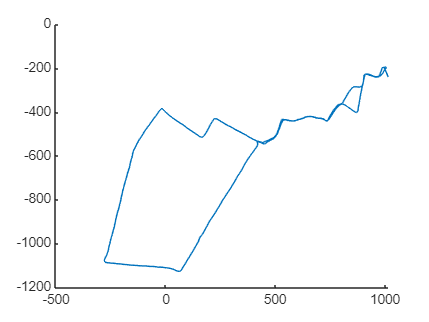

for node=keys(calculatedPositions)'
    % figure
    positions = values(calculatedPositions{node})';
    positions = positions(1:10:end);
    % actualX = bikeData{1}.x(keys(positions))';
    % actualY = bikeData{1}.y(keys(positions))';

    supposedX = bikeData{1}.x(toReceive{i}(2, :));
    supposedY = bikeData{1}.y(toReceive{i}(2, :));

    predictedX = [];
    predictedY = [];


    for position = positions
        predictedX(end+1) = position{1}(1);
        predictedY(end+1) = position{1}(2);
    end

    % predictedY = values(calculatedPositions{node})

    
    s2 = scatter(predictedX, predictedY, 10, "filled", MarkerFaceColor="red");
    % s1 = scatter(actualX, actualY, 10, "filled", MarkerFaceColor="green");
    s1 = scatter(supposedX, supposedY, 10, "filled", MarkerFaceColor="green");
    % hold on
    % s1 = plot([actualX, actualY], 10, "filled", MarkerFaceColor="green");
    % plot(actualX, actualY)
    % hold off

    % % for i = keys(calculatedPositions{node})
    %     scatter(bikeData{1}(i, ["x" "y"]), MarkerFaceColor="green")
    %     scatter(calculatedPositions{node}{i}, "red")
    % end
    i = i + 1;
end

% hold off

if newSimulation
    if eventBased
        save("Output\results\event_based_simulation_" + strrep(string(datetime), ":", ".") + ".mat")
    else
        save("Output\results\periodic_based_simulation_" + strrep(string(datetime), ":", ".") + ".mat")
    end
end